## Q1

x=[1 2 3 4 5 6 7 8 9 10]';
y=[2 4 7 8 10 13 14 16 17 20]';

X = [ones(size(x,1),1) x];
[b, bint, r, rint, stats] = regress(y,X);

sum(abs(r))

ans = 3.8667

## Q4-5

x=[1; 2; 3; 4; 5; 6; 7; 8; 9; 10];
y=[0; 0; 0; 1; 0; 0; 1; 1; 1; 1];
% table_ = table(x,y);
% 
% modelspec = ['y ~ x'];
% mdl = fitglm(table_, modelspec, Distribution='binomial')

x0 = -6.73

x0 = -6.7300

a = 0.88

a = 0.8800

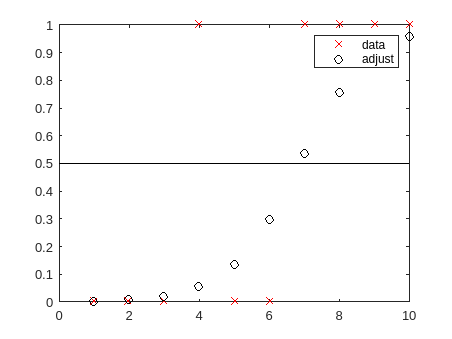


ylogist = zeros(size(x,1),1);
for ii=1:size(x,1)
    ylogist(ii) = 1/(1+exp(-x(ii)-x0)/a);
end

figure(4)
plot(x,y,'xr')
hold on
plot(x,ylogist,'ok')
plot([0 10],[0.5 0.5],'k')
legend('data','adjust')
hold off


sum(abs(y-ylogist))

ans = 2.2626

## Q7

x=[1 2 3 4 5 6 7 8 9 10]';
y=[10.0 8.9 8.0 7.1 6.0 4.9 4.1 3.2 1.9 1.1]';

p = polyfit(x,y,1)

p =    -0.9891   10.9600


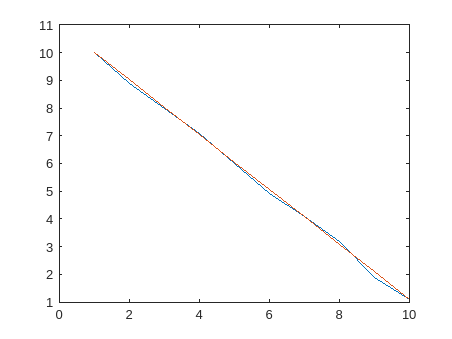

y1 = 11-.99.*x;
figure(7)
plot(x,y)
hold on
plot(x,y1)
hold off

## Q9

TP = 22;
FP = 11;
TN = 60;
FN = 7;

TPR = TP/(TP+FN)

TPR = 0.7586

FPR = FP/(FP+TN)

FPR = 0.1549